# Random Numbers

## Why Random Numbers

Generating a series of random numbers is important for 

- Cryptography

- Statistical sampling (statistic mechanics, anyone?)

- Signal analysis

- Monte Carlo simulations

- Monte Carlo integrations

- Game design *(No Man’s Sky, Minecraft, Civilization)*

## Random Number Generators and Seeds

- Every random number generator actually generates ***pseudorandom***numbers and thus needs a “starting point” – *a seed*

- The most *basic* generator is the *Linear Congruential Random Number Generator*


$$x' = (ax + c)\, mod\,m$$


- The 'seed' being *x. *The numbers*c, a,*and *m* being parameters.

- In MATLAB, you can set the seed (**but shouldn’t unless you have a good reason **– *reproducibility of a random array*)

s = rng(now,'twister')

s = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]

rng(s)
first = rand(5,1) % produce 5 random numbers

first =    0.814723686393179
   0.905791937075619
   0.126986816293506
   0.913375856139019
   0.632359246225410


rng(s)
second = rand(5,1)

second =    0.814723686393179
   0.905791937075619
   0.126986816293506
   0.913375856139019
   0.632359246225410


first - second

ans =      0
     0
     0
     0
     0


## *Linear Congruential Random Number Generator*

- The basis for the 1960s Scientific SubroutingPackage (SSP) on the IBM mainframe computers

- Used parameters

*a = 65539 = *$2^{16} +3$

*c =0 *

*m = *$2^{31}$

- **Bad Choice**: this produced highly correlated random numbers (Which is very bad!!!)

- *Mersenne twistor *is a more common rng today

Period of $2^{19937} -1$

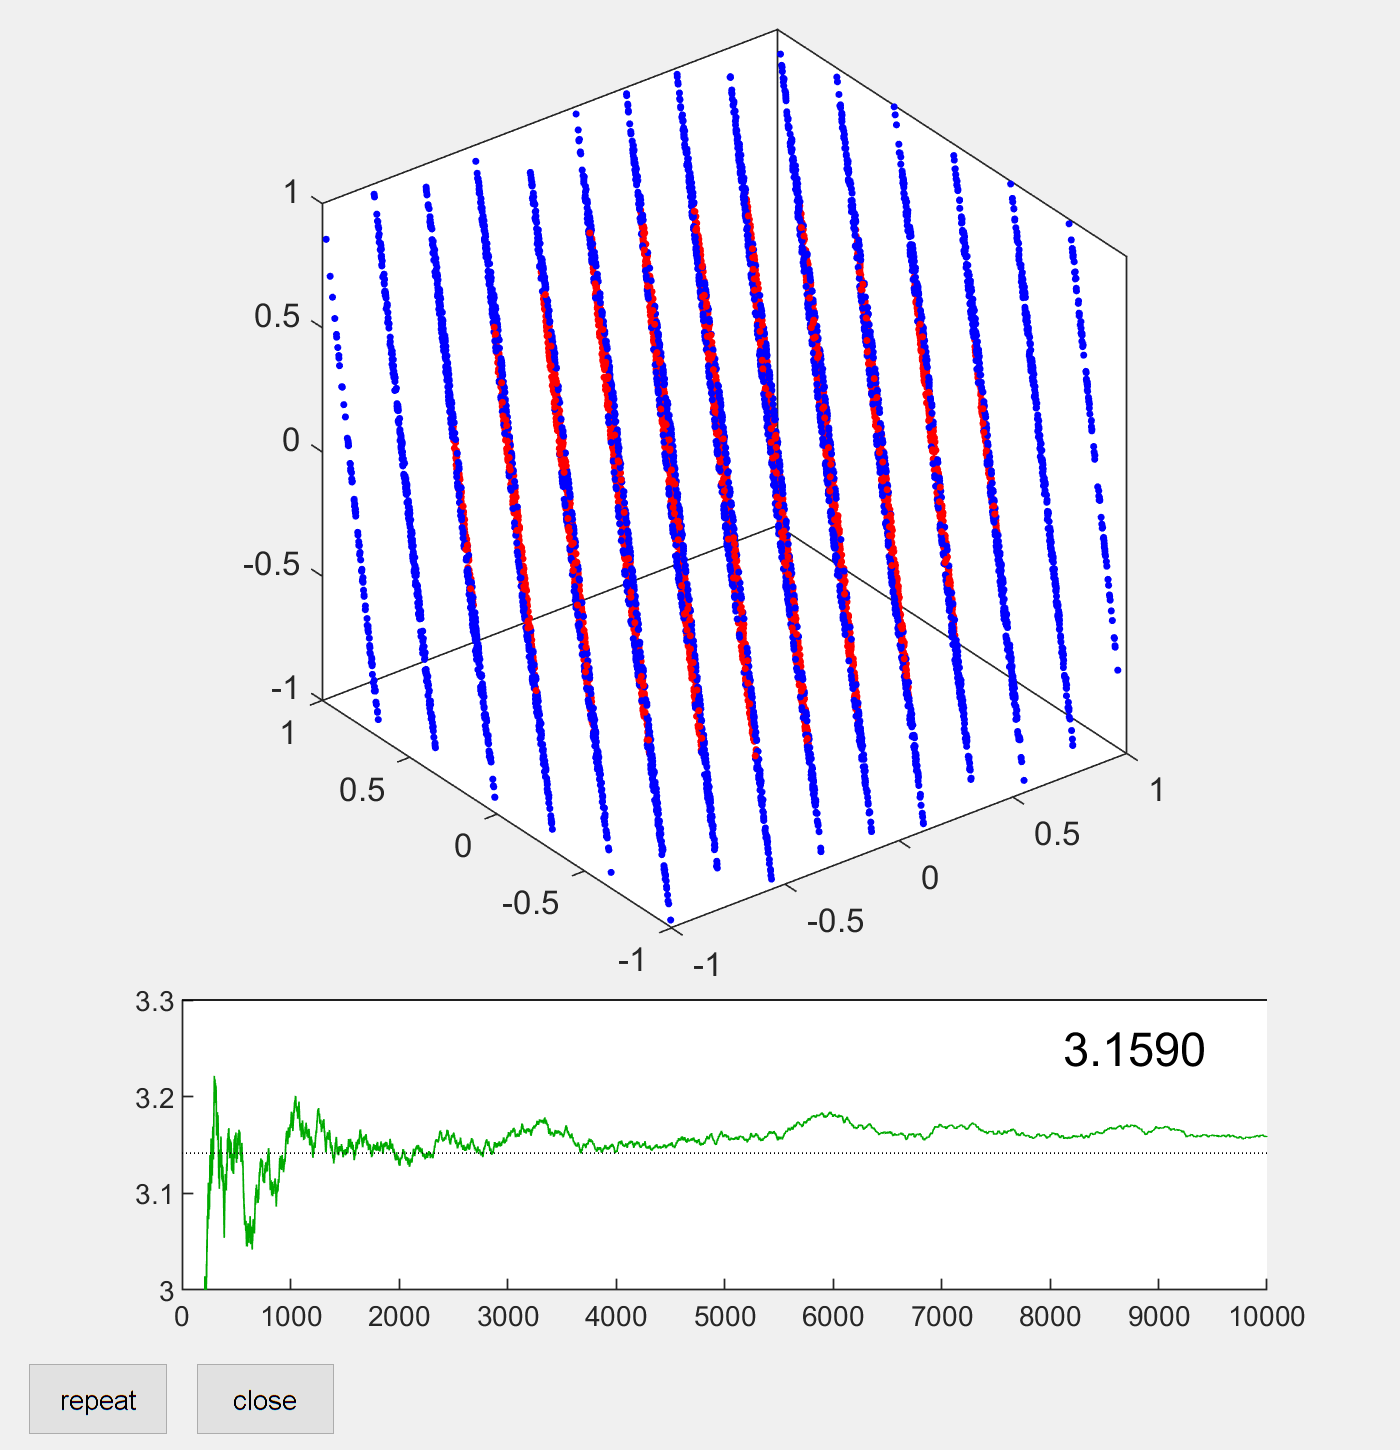

randgui('randssp')

## Example: Decay of An Isotope

- The radioisotope thallium-208 decays to a stable lead-208 atom with a half-life of 3.053 minutes

- The *average *number of particles left is 


$$N(t) = N_0 (2^{-t/t_{1/2}})$$


- The probability that any *one* thallium has decay is 


$$p(t) = 1 - \frac{N(t)}{N(0)} = 1 -2^{-t/t_{1/2}}$$


this is the probability that a single atom decays in time *t*

*Look at *`isotopedecay.m` and` isotopedecay2.m `(Thallium Decay Problem)

- `isotopedecay.m` produces a series of random numbers that are compared to the probability of decay at time *t* and then used to calculate the amount of thallium left

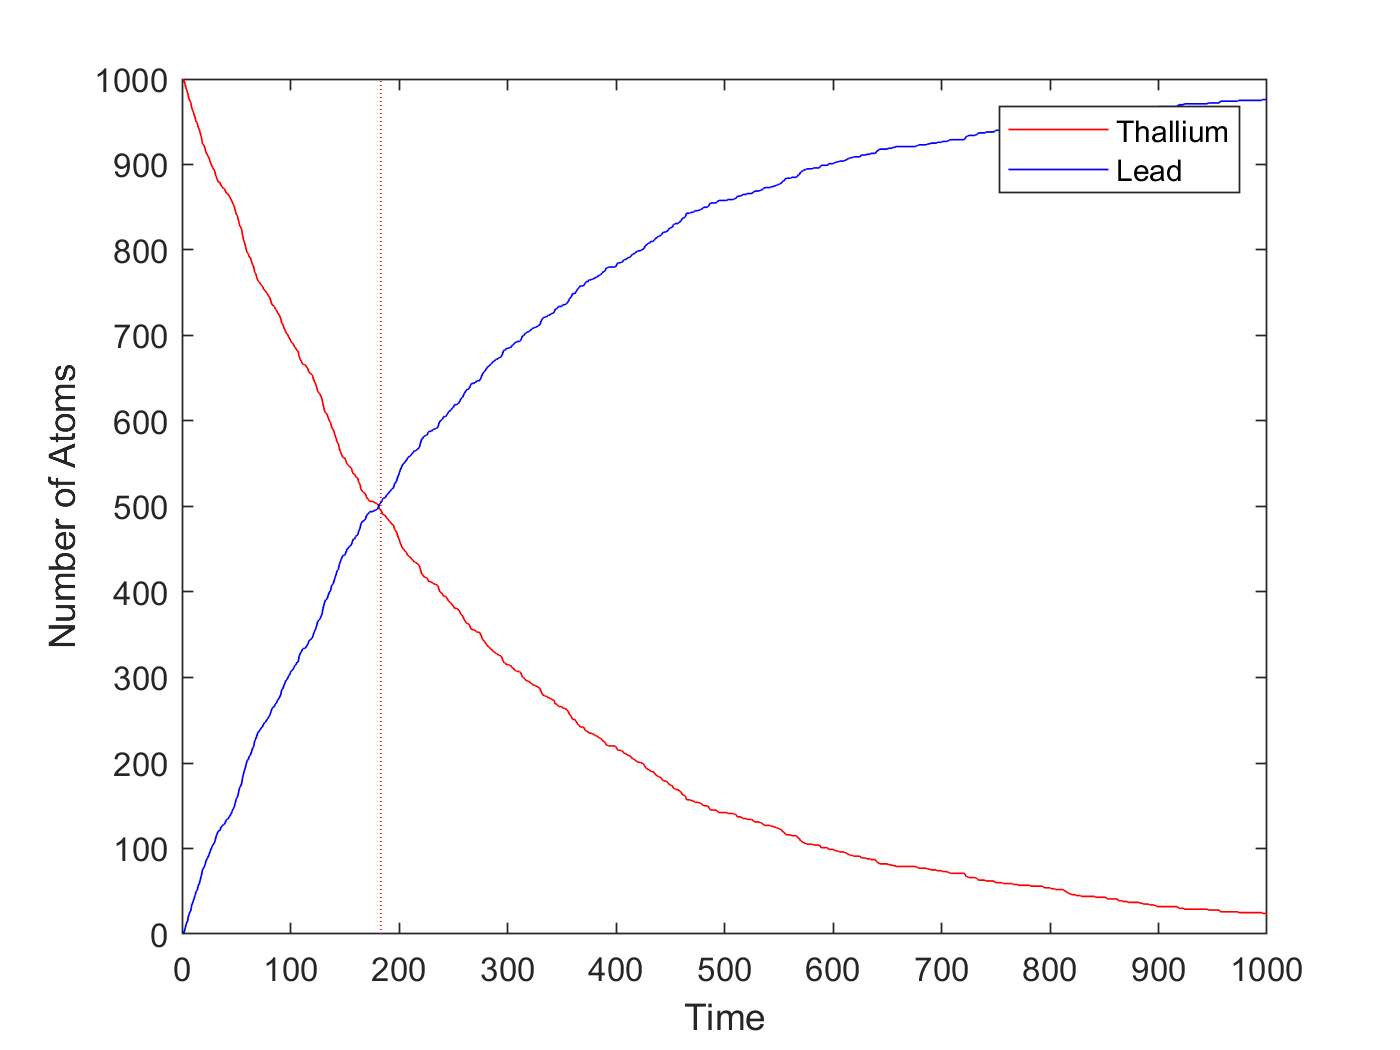

isotopedecay

## Non-Uniform Random Numbers

- The probability the a particle decays in time *t* is 


$$1-2^{-t/t_{1/2}}$$


- The probability that it decays in a small time period *dt*


$$1-2^{dt/t_{1/2}} = 1-exp\left[\frac{t}{t_{1/2}ln(2)}\right] \approx \frac{dt}{\tau}$$


What is the probability of decay in between the times *t *and *t+dt*?

- The particle has to not decay up to *t*, 


$$P(t) = e^{-t/\tau}$$


- Then during the next *dt**, *


$$P(dt) = \frac{dt}{\tau}$$


- The total probability is then


$$P(t) = e^{-t/t_{1/2}}\left(\frac{dt}{\tau}\right)$$


Therefore a “better program” would have drawn from an exponential distribution to represent the times at which a particle decayed (see `isotopedecay2.m`)

## `RAND`

`rand` produces random numbers from a uniform distribution between 0 and 1

- produces an n x n matrix of random numbers

- produces a n x m x ___ matrix of random numbers

- 'type' specifies the numeric type returned by the function

`double / single`

- can also use p as a model for the numeric type returned

r1 = rand
r2 = rand(5)
r3 = rand([2,2])
x = single(34);
r4 = rand(3,'like',x)
rand([5000 1])

## RANDI

`randi `returns a random** integer**

- returns random numbers between `imin` an `imax`

- returns an `n1` x `n2` x … matrix of random number

- can specify the return type (`'int8', 'int16', 'int32'`,...) with classname or an example number *p*

ri = randi(20)
rm = randi(20,[4 4])
rmr = randi([3 15],[2 2])
rmt = randi([4 10],2,'int8')

## RANDN

`randn` returns a normally distributed number

- can return an *n x n *matrix or a *n1 x **nN* matrix

- can specify the return type (`'int8', 'int16', 'int32'`,...) with `classname` or an example number p

randn(4)
randn(4,1)
hist(randn(500,1))

## RANDOM

Returns a random number taken from a probability distribution

- Make a probability distribution by 

- `distname` is a char array with the distribution’s name: `‘Gamma’ `or `‘Normal’`

- `‘name’` is also a name of the probability distribution – use this to skip creating a pd explicitly